- Initialize  for example $\delta =\left\lbrack -15,-10,-5,\;0,5,10,15\right\rbrack$*, *$f_{\textrm{dri}} =1$*, *$f_{\textrm{brk}} =0$*;*

- choose $\textrm{dt}=0\ldotp 1$, calculate path $x=x+\left(\dot{\;x} \;\textrm{dt}\right)$,      there are total $n=\;\textrm{length}\left(\delta \;\right)$ paths

- determine $f_{\textrm{dri}}$ based on $v=v+\frac{\left(f_{\textrm{dri}} +f_{\textrm{brk}} -f_{\textrm{drag}} \right)}{m\;}\textrm{dt}$

- Does the $\delta \;$need to be updated based on curvature?

- **How to decide the next intputs?**

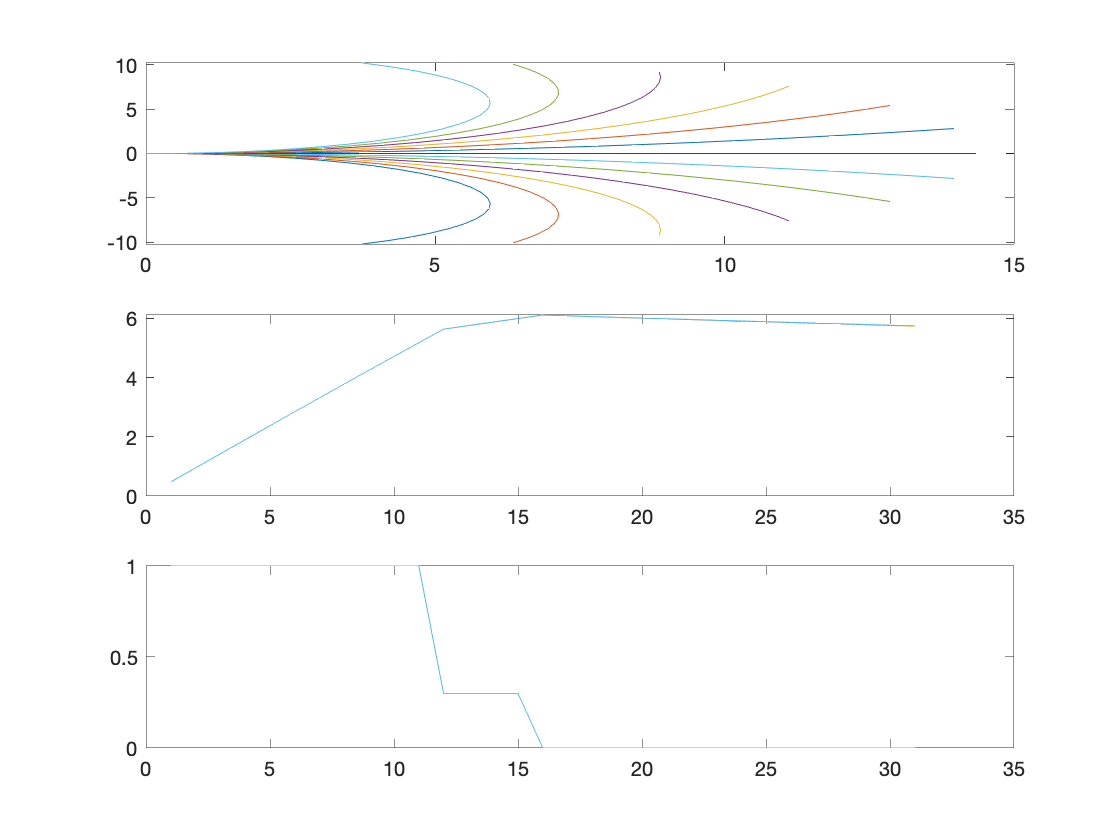

clear all;
close all;

% sample time
dt= 0.1;
t_list= (0:dt:3)';

u_steer_dis= deg2rad((-15:2.5:15)');
u_steer_list=[];

for i= 1:length(u_steer_dis)
    u_steer_tmp=repmat(u_steer_dis(i),length(t_list),1);
    u_steer_list= [u_steer_list,u_steer_tmp];
end

s0= [0;0;0;0];
s=[];

figure();
for k=1:size(u_steer_list,2)
    [s_tmp, u_tmp] = StateUpdate(s0, u_steer_list(:,k), t_list, dt);
    s=[s, s_tmp];
    subplot(3,1,1);
    plot(s_tmp(1,:), s_tmp(2,:));
    hold on;
    
    subplot(3,1,2);
    plot(s_tmp(4,:));
    hold on;
    
    subplot(3,1,3);
    plot(u_tmp(2,:));
    hold on;
end